# Importing DATA


clear all; clc; 
format long g;
sensor_data= readmatrix('fort600.xlsx');
% sensordata = dlarray(sensor_data);
sensordata = sensor_data(1:1597,:);% To get 1600 points
Data_in = sensordata(1,1:8);
Data_in = [Data_in;sensordata(1,9:16)]

Data_in =                  4.3119979                0.93504871                 1.2126992                0.14990909                 1.3609625                 1.2958904                 1.4728005                -7.8152902
                 4.6370932                 1.3317006                 1.0280635                0.48291254                0.54450921                 1.7415827                0.65598598                -7.4425119


Data_in = [Data_in; sensordata(1,17:24)]

Data_in =                  4.3119979                0.93504871                 1.2126992                0.14990909                 1.3609625                 1.2958904                 1.4728005                -7.8152902
                 4.6370932                 1.3317006                 1.0280635                0.48291254                0.54450921                 1.7415827                0.65598598                -7.4425119
                  4.106522                0.83127903                  1.010114                0.15544619                 1.0874505                  1.525336                  1.203144                -7.7867044


for i = 1:1597
    Data_in = [Data_in; sensordata(i,25:32)];
end

data = Data_in';
num_data = 1600;

## visualise Data

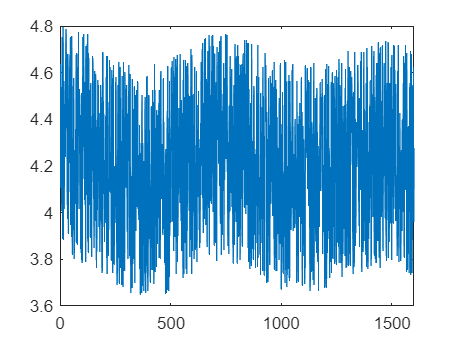

% stackedplot(Data_in');
plot(data(1,:));

sensorN =8;

num_step_train = floor(0.9*num_data);
train = data(sensorN,1:(num_step_train+1));
test = data(sensorN,(num_step_train+1):end);

## standardise thedata for zero mean and unit variance

mu = mean(train);
sigma = std(train);
std_train_data = (train - mu)/sigma;
XTrain = std_train_data(1:end-1);
YTrain = std_train_data(2:end);
num_features = 1;
num_responses = 1;
num_hidden_units = 200;
layers = [sequenceInputLayer(num_features),lstmLayer(num_hidden_units),fullyConnectedLayer(num_responses),regressionLayer];
layers

layers =   1×4 Layer array with layers:

     1   ''   Sequence Input      Sequence input with 1 dimensions
     2   ''   LSTM                LSTM with 200 hidden units
     3   ''   Fully Connected     1 fully connected layer
     4   ''   Regression Output   mean-squared-error

options = trainingOptions('adam', 'MaxEpochs',500,...
    'GradientThreshold',1,'InitialLearnRate',0.005,...
    'LearnRateSchedule','piecewise','LearnRateDropPeriod',125,...
    'LearnRateDropFactor',0.2,'Verbose',0,'Plots','training-progress');
options

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9
      SquaredGradientDecayFactor: 0.999
                         Epsilon: 1e-08
                InitialLearnRate: 0.005
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.2
             LearnRateDropPeriod: 125
                L2Regularization: 0.0001
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: 1
                       MaxEpochs: 500
                   MiniBatchSize: 128
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
       

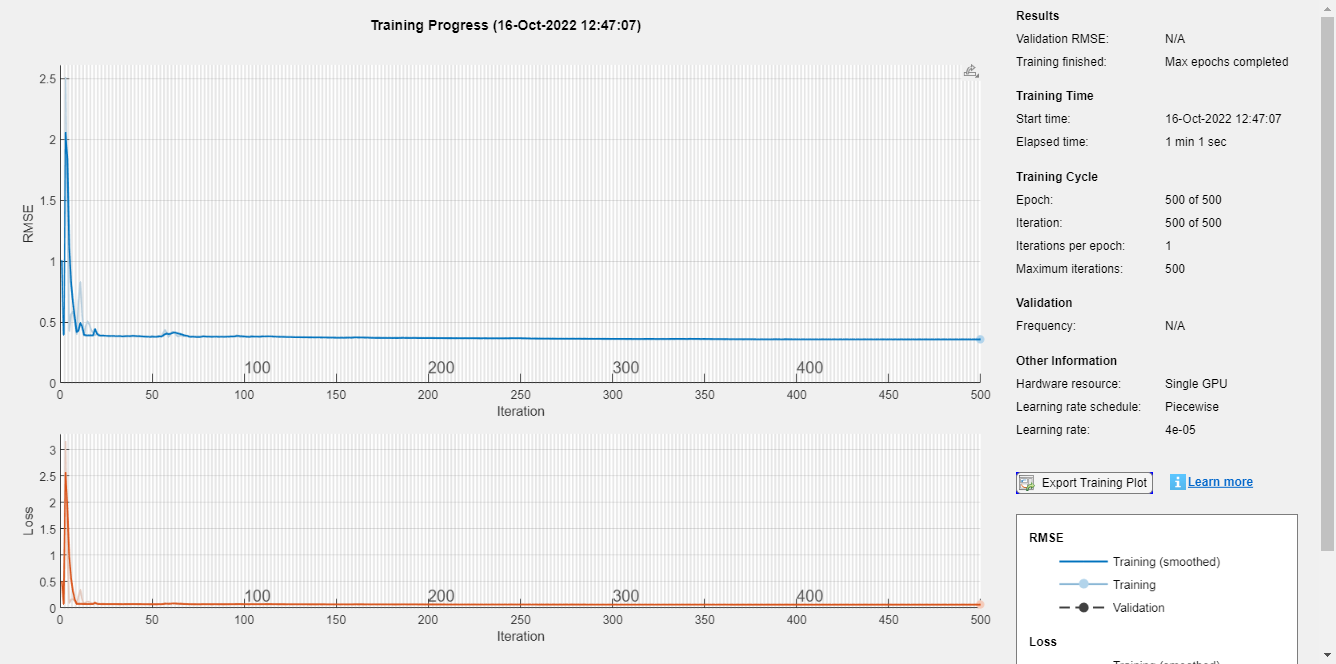

net = trainNetwork(XTrain,YTrain,layers,options);

std_test_data = (test - mu)/sigma;
XTest = std_test_data(1:end-1);
net = predictAndUpdateState(net, XTrain);
format long g;
[net, YPred] = predictAndUpdateState(net,YTrain(end)); % make first prediction using the last time step of training response : YTrain(end)
num_step_test = numel(XTest);
for i= 2:num_step_test
    [net,YPred(:,i)] = predictAndUpdateState(net, YPred(:,i-1));
end

% Destandardise the test data
YPred = YPred*sigma + mu;
YTest = test(2:end);
rmse =sqrt(mean((YPred - YTest).^2));

## Plot for prediction on test data

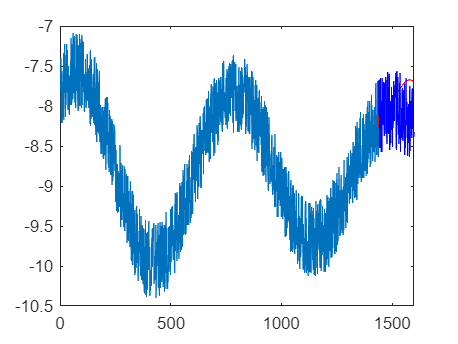

figure(10);
plot(train(1:end-1));
hold on;
idx = num_step_train:(num_step_train+num_step_test);
plot(idx, [data(sensorN,num_step_train),YPred],'r')

plot(idx, [data(sensorN,num_step_train),YTest],'b')